## Dengue mosquito detection 

Dengue fever, caused by the dengue virus and transmitted primarily by the Aedes mosquito species, poses a significant global health challenge. The disease manifests in various forms, ranging from asymptomatic cases to severe and potentially fatal outcomes. Early detection and intervention are crucial in controlling the spread of dengue fever and mitigating its impact on affected communities.

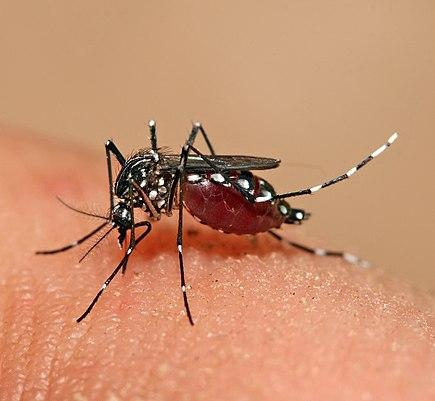

                                                        *src:https://en.wikipedia.org/wiki/Dengue_fever*

### 01.Read the audio file in the time domain 

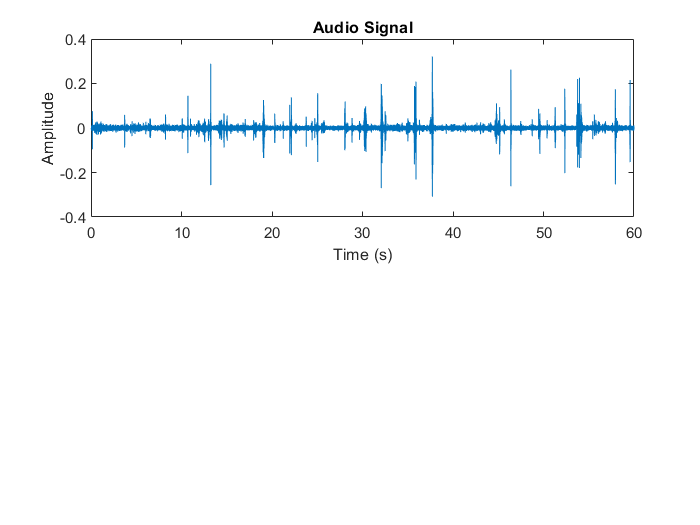

% Full path to the audio file
full_path = 'E:\5th Semester\01-Our notes\EC5011-Digital signal processing\03-Task\02\data_mosquito\dengue\train_dengue\Voice0135 AEGY10130f.wav';

% Load audio file
[y, Fs] = audioread(full_path);

% Calculate the time axis
t = (0:length(y)-1) / Fs;

% Plot the time-domain waveform
plot(t, y);
title('Audio Signal');
xlabel('Time (s)');
ylabel('Amplitude');

### 02.Filter the sound to reduce the noice of the signal

apply filter and  it's important to balance noise reduction with preserving the desired audio content.

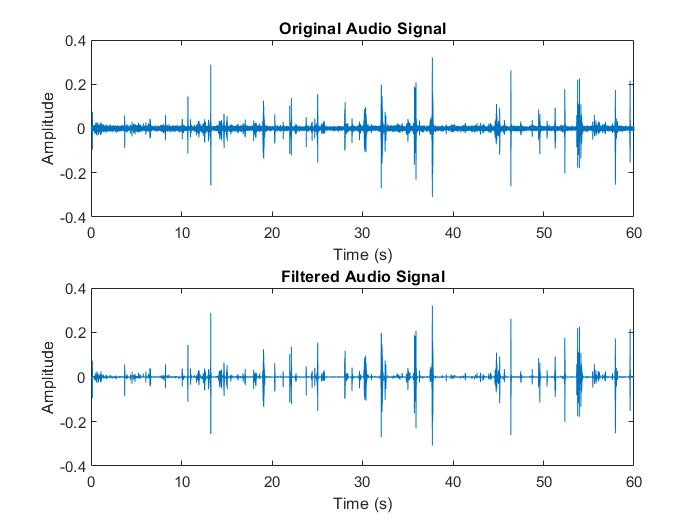


y_filtered = wiener2(y, [3 3]);

% Plot the original and filtered signals
t = (0:length(y)-1) / Fs;
subplot(2,1,1);
plot(t, y);
title('Original Audio Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2,1,2);
plot(t, y_filtered);
title('Filtered Audio Signal');
xlabel('Time (s)');
ylabel('Amplitude');

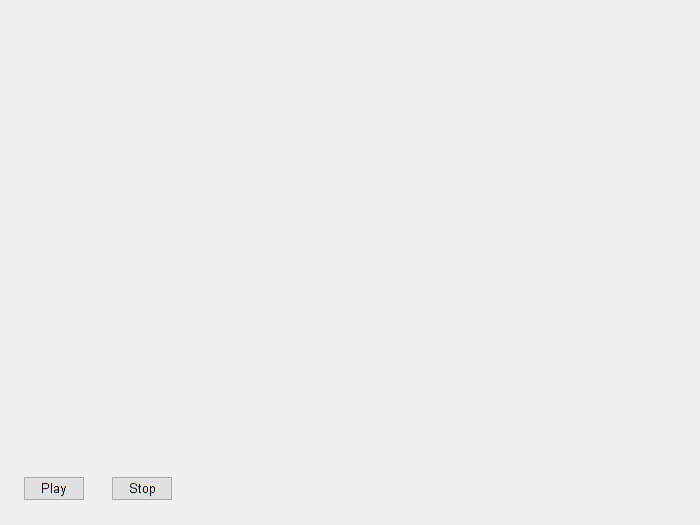


% Create audioplayer object
player = audioplayer(y_filtered, Fs);

% Create figure and buttons
fig = figure;
playButton = uicontrol('Style', 'pushbutton', 'String', 'Play', 'Position', [20 20 50 20], 'Callback', {@playCallback, player});
stopButton = uicontrol('Style', 'pushbutton', 'String', 'Stop', 'Position', [90 20 50 20], 'Callback', {@stopCallback, player});

### 03.Make the frquency spectrum of the audio

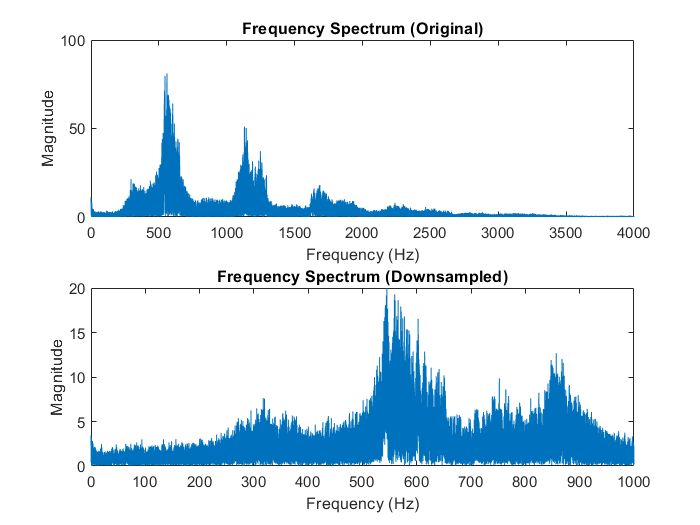

% Frequency spectrum plot of the original filtered signal
subplot(2,1,1);
N = length(y_filtered);
Y = fft(y_filtered);
yshift = fftshift(Y);
fshift = (-N/2:N/2-1)*(Fs/N); % Corrected frequency vector
plot(fshift, abs(yshift));
title('Frequency Spectrum (Original)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
xlim([0 Fs/2]);

% Downsample the signal
downsample_factor = 4; % Adjust as needed
y_downsampled = downsample(y_filtered, downsample_factor);
Fs_downsampled = Fs / downsample_factor;

% Frequency spectrum plot of the downsampled signal
subplot(2,1,2);
N_downsampled = length(y_downsampled);
Y_downsampled = fft(y_downsampled);
yshift_downsampled = fftshift(Y_downsampled);
fshift_downsampled = (-N_downsampled/2:N_downsampled/2-1)*(Fs_downsampled/N_downsampled); % Corrected frequency vector
plot(fshift_downsampled, abs(yshift_downsampled));
title('Frequency Spectrum (Downsampled)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
xlim([0 Fs_downsampled/2]);

From manual inspection there is high magnitude in 

- 500-700Hz

- 1050 - 1300 Hz

### 04.Get another audio clip and plot the frequency spectrum

sampling rate is 44kHz.So it is downsampled to get same sampling rate to analize

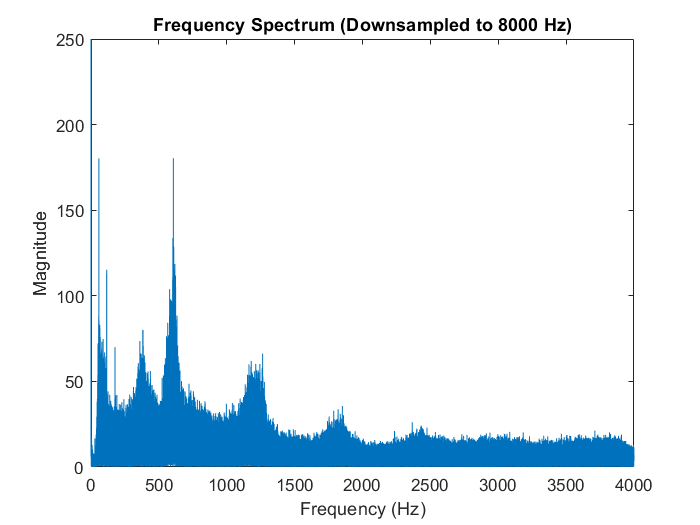

% Full path to the audio file
full_path = 'E:\5th Semester\01-Our notes\EC5011-Digital signal processing\03-Task\02\data_mosquito\dengue\train_dengue\11-16-2016-125240 albopictus f.wav';

% Load audio file
[y, Fs] = audioread(full_path);

y = wiener2(y, [3 3]);

% Resample the audio signal to 8000 Hz
targetFs = 8000; % Desired sampling rate
y_downsampled = resample(y, targetFs, Fs);

% Calculate the FFT and frequency vector for the downsampled signal
N_downsampled = length(y_downsampled);
Y_downsampled = fft(y_downsampled);
Y_downsampled_shifted = fftshift(Y_downsampled); % Shift zero frequency to the center
f_downsampled = (-N_downsampled/2:N_downsampled/2-1) * (targetFs / N_downsampled);

% Plot the frequency spectrum of the downsampled signal
figure;
plot(f_downsampled, abs(Y_downsampled_shifted));
title('Frequency Spectrum (Downsampled to 8000 Hz)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
xlim([0 targetFs/2]);

From manual inspection it is clear that there is high magnitude in 

- 500-700Hz

- 1050 - 1300 Hz

## 05.Get all the spectrum of the audio files to see the spectrum

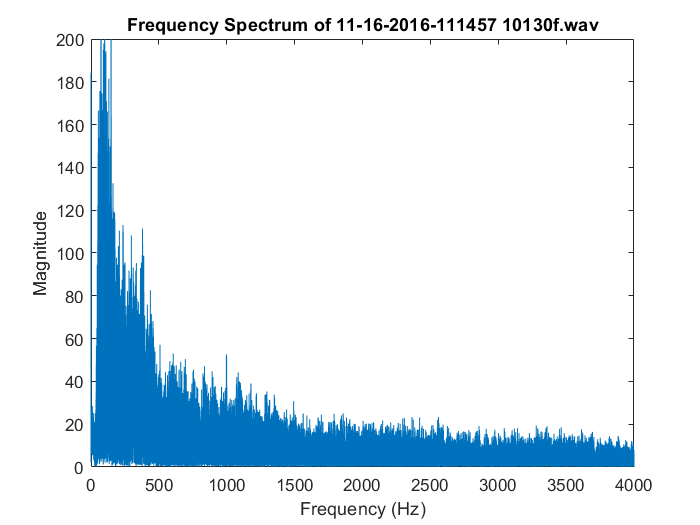

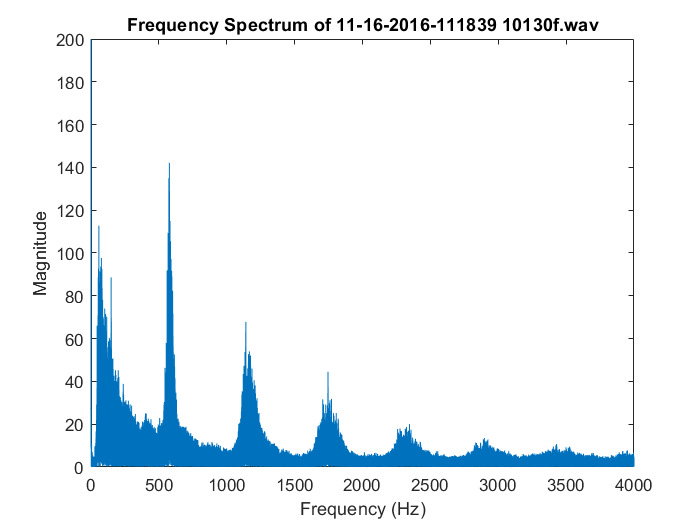

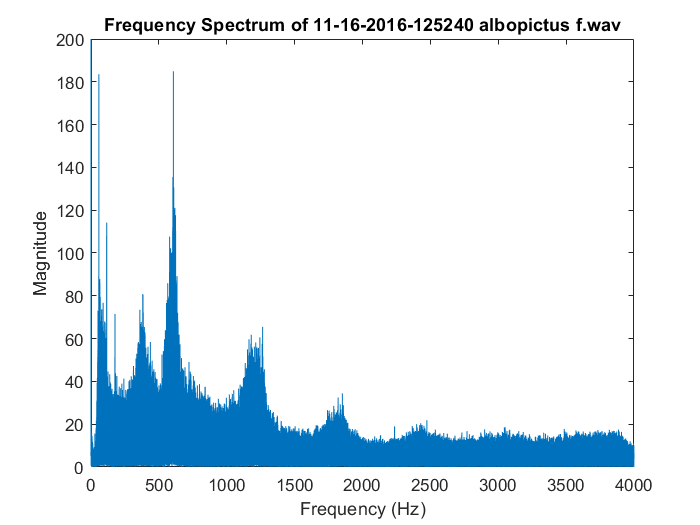

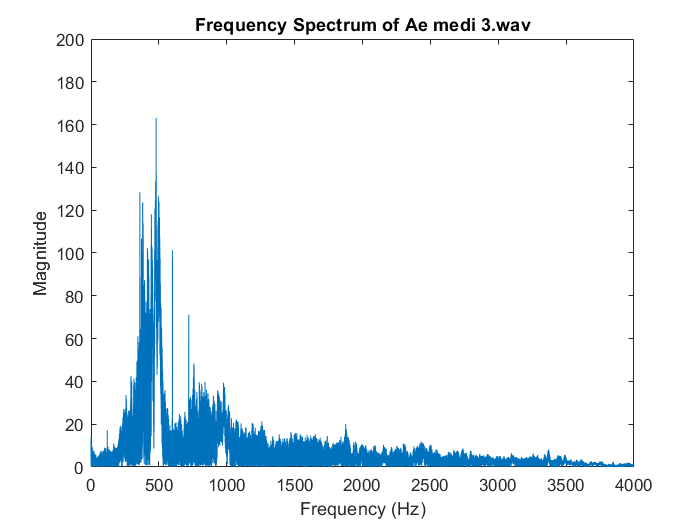

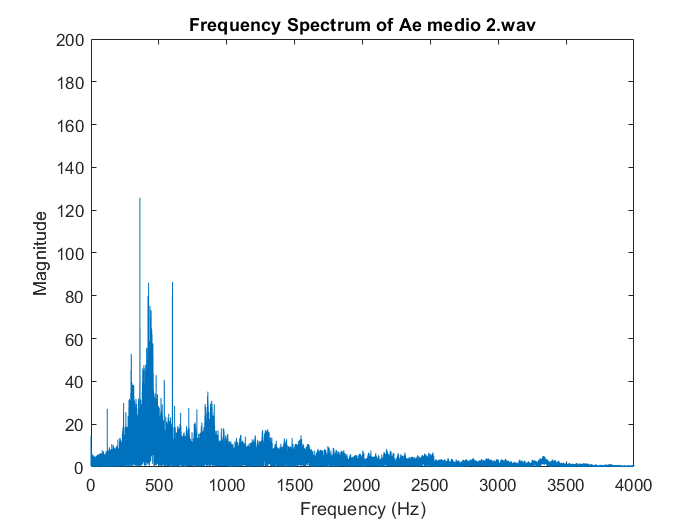

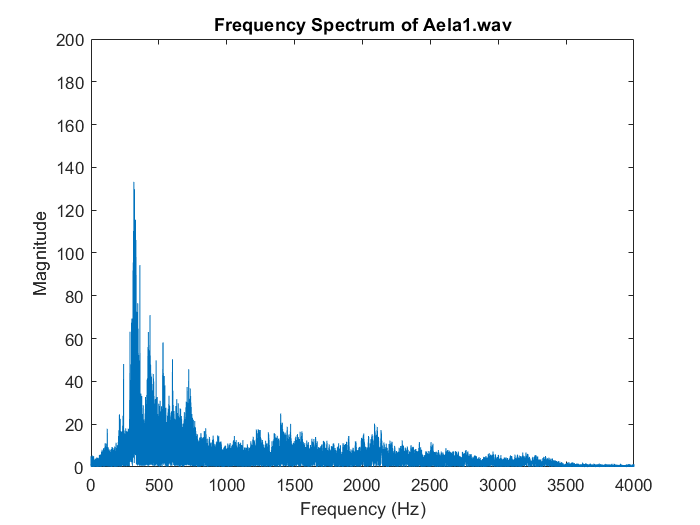

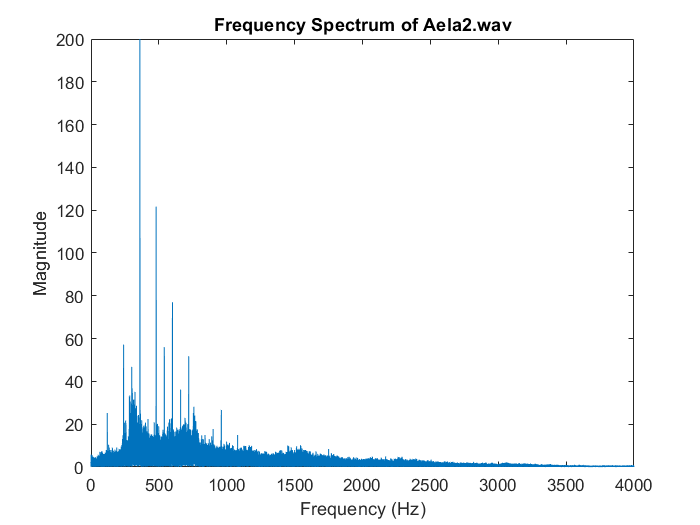

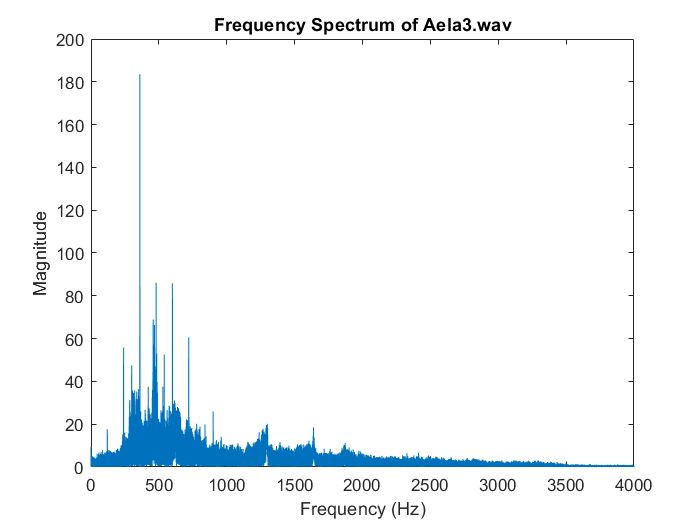

% Define the folder containing the audio files
folder_path = 'E:\5th Semester\01-Our notes\EC5011-Digital signal processing\03-Task\02\data_mosquito\dengue\train_dengue\';

% List all .wav files in the folder
audio_files = dir(fullfile(folder_path, '*.wav'));

% Target sampling rate for resampling
targetFs = 8000;

% Get a list of all audio files in the folder
audio_files = dir(fullfile(folder_path, '*.wav')); % Assuming .wav files

num_files = length(audio_files);

% Initialize a cell array to store spectra
spectra = cell(num_files, 1);
frequencies = cell(num_files, 1);

% Loop through each file to compute its spectrum
% Loop through each file to compute its spectrum and plot
for k = 1:num_files
    % Get the full path of the audio file
    file_path = fullfile(folder_path, audio_files(k).name);
    
    % Read the audio file
    [y, Fs] = audioread(file_path);
    
    % Resample the audio signal to the target sampling rate if necessary
    if Fs ~= targetFs
        y = resample(y, targetFs, Fs);
    end
    
    y = wiener2(y, [3 3]);
    
    % Compute the FFT of the resampled signal
    N = length(y);
    Y = fft(y, N); % Ensure the FFT is computed over N points
    Y_shifted = fftshift(Y); % Shift zero frequency to the center
    spectrum = abs(Y_shifted);
    
    % Compute frequency axis
    f = (-N/2:N/2-1) * (targetFs / N);
    
    % Plot the spectrum for this file
    figure;
    plot(f, spectrum);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
    title(['Frequency Spectrum of ', audio_files(k).name], 'Interpreter', 'none');
    xlim([0 4000])
    ylim([0 200])
end

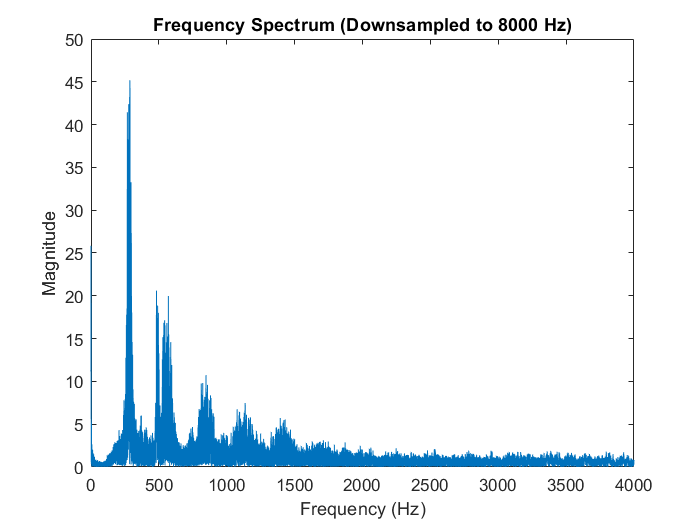

% plot non-dengue spectrum to see the frequencies
% Full path to the audio file
full_path = 'E:\5th Semester\01-Our notes\EC5011-Digital signal processing\03-Task\02\data_mosquito\non-dengue\train_non_dengue\Big Black Mosquito Glen Park - March 2016 - Ds1.wav';

% Load audio file
[y, Fs] = audioread(full_path);

y = wiener2(y, [3 3]);

% Resample the audio signal to 8000 Hz
targetFs = 8000; % Desired sampling rate
y_downsampled = resample(y, targetFs, Fs);

% Calculate the FFT and frequency vector for the downsampled signal
N_downsampled = length(y_downsampled);
Y_downsampled = fft(y_downsampled);
Y_downsampled_shifted = fftshift(Y_downsampled); % Shift zero frequency to the center
f_downsampled = (-N_downsampled/2:N_downsampled/2-1) * (targetFs / N_downsampled);

% Plot the frequency spectrum of the downsampled signal
figure;
plot(f_downsampled, abs(Y_downsampled_shifted));
title('Frequency Spectrum (Downsampled to 8000 Hz)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
xlim([0 targetFs/2]);

## Design the Filter based on frequency

% Define the folder paths and target sampling rate
folder_path_dengue = 'E:\5th Semester\01-Our notes\EC5011-Digital signal processing\03-Task\02\data_mosquito\dengue\train_dengue'; % Replace with your folder path
folder_path_test_dengue = 'E:\5th Semester\01-Our notes\EC5011-Digital signal processing\03-Task\02\data_mosquito\dengue\test_dengue'; % Replace with your folder path

% Define the frequency ranges for dengue sounds
dengue_bands = [550 650; 1050 1200 ; 1650 1800]; %add 1650:1850 to improve acurracy of the filter 

% Define FFT length
L2 = 8192;

% Design bandpass filters for dengue frequency ranges
[num_band1, den_band1] = butter(6, dengue_bands(1,:) / (targetFs / 2), 'bandpass');
[num_band2, den_band2] = butter(6, dengue_bands(2,:) / (targetFs / 2), 'bandpass');
[num_band3, den_band3] = butter(6, dengue_bands(3,:) / (targetFs / 2), 'bandpass');

% Get list of audio files for testing
Te_dengue = dir(fullfile(folder_path_dengue, '*.wav'));
Te_test_dengue = dir(fullfile(folder_path_test_dengue, '*.wav'));


% Define threshold for classification
threshold = 150; % Adjust based on your dataset

### Test the data for the train and test data for dengue

- accuracy for the train data for the dengue - 80.95**%**

- accuracy for the test data for the dengue - 88.8**%**

% Initialize counters
total_dengue = 0;
total_non_dengue = 0;

% Process and classify dengue sounds
for n = 1:length(Te_dengue)
    file_path = fullfile(folder_path_dengue, Te_dengue(n).name);
    is_dengue = classify_audio(file_path, num_band1, den_band1, num_band2, den_band2, num_band3, den_band3, L2, threshold);
    if is_dengue
        total_dengue = total_dengue + 1;
    else
        total_non_dengue = total_non_dengue + 1;
    end
end

Non-Dengue: E:\5th Semester\01-Our notes\EC5011-Digital signal processing\03-Task\02\data_mosquito\dengue\train_dengue\11-16-2016-111457 10130f.wav
Dengue: E:\5th Semester\01-Our notes\EC5011-Digital signal processing\03-Task\02\data_mosquito\dengue\train_dengue\11-16-2016-111839 10130f.wav
Non-Dengue: E:\5th Semester\01-Our notes\EC5011-Digital signal processing\03-Task\02\data_mosquito\dengue\train_dengue\11-16-2016-125240 albopictus f.wav
Dengue: E:\5th Semester\01-Our notes\EC5011-Digital signal processing\03-Task\02\data_mosquito\dengue\train_dengue\Ae medi 3.wav
Dengue: E:\5th Semester\01-Our notes\EC5011-Digital signal processing\03-Task\02\data_mosquito\dengue\train_dengue\Ae medio 2.wav
Dengue: E:\5th Semester\01-Our notes\EC5011-Digital signal processing\03-Task\02\data_mosquito\dengue\train_dengue\Aela1.wav
Dengue: E:\5th Semester\01-Our notes\EC5011-Digital signal processing\03-Task\02\data_mosquito\dengue\train_dengue\Aela2.wav
Dengue: E:\5th Semester\01-Our notes\EC5011-D


% Display results
disp(['Total Dengue Files: ', num2str(total_dengue)]);

Total Dengue Files: 18


disp(['Total Non-Dengue Files: ', num2str(total_non_dengue)]);

Total Non-Dengue Files: 3


% Initialize counters for test-dengue sounds
total_test_dengue = 0;
total_test_non_dengue = 0;

% Process and classify test-dengue sounds
for n = 1:length(Te_test_dengue)
    file_path = fullfile(folder_path_test_dengue, Te_test_dengue(n).name);
    is_dengue = classify_audio(file_path, num_band1, den_band1, num_band2, den_band2, num_band3, den_band3, L2, threshold);
    if is_dengue
        total_test_dengue = total_test_dengue + 1;
    else
        total_test_non_dengue = total_test_non_dengue + 1;
    end
end

Non-Dengue: E:\5th Semester\01-Our notes\EC5011-Digital signal processing\03-Task\02\data_mosquito\dengue\test_dengue\10130f.wav
Dengue: E:\5th Semester\01-Our notes\EC5011-Digital signal processing\03-Task\02\data_mosquito\dengue\test_dengue\Ae medio 4.wav
Dengue: E:\5th Semester\01-Our notes\EC5011-Digital signal processing\03-Task\02\data_mosquito\dengue\test_dengue\Aela4.wav
Dengue: E:\5th Semester\01-Our notes\EC5011-Digital signal processing\03-Task\02\data_mosquito\dengue\test_dengue\Voice0121 AEGY ui.wav
Dengue: E:\5th Semester\01-Our notes\EC5011-Digital signal processing\03-Task\02\data_mosquito\dengue\test_dengue\Voice0122.wav
Dengue: E:\5th Semester\01-Our notes\EC5011-Digital signal processing\03-Task\02\data_mosquito\dengue\test_dengue\Voice0132.wav
Dengue: E:\5th Semester\01-Our notes\EC5011-Digital signal processing\03-Task\02\data_mosquito\dengue\test_dengue\Voice0136 albof.wav
Dengue: E:\5th Semester\01-Our notes\EC5011-Digital signal processing\03-Task\02\data_mosqui

% Display results for test-dengue files
disp(['Total Test-Dengue Files: ', num2str(total_test_dengue)]);

Total Test-Dengue Files: 8


disp(['Total Test-Non-Dengue Files: ', num2str(total_test_non_dengue)]);

Total Test-Non-Dengue Files: 1


### Test the data for the train and test data for non-dengue

folder_path_non_dengue = 'E:\5th Semester\01-Our notes\EC5011-Digital signal processing\03-Task\02\data_mosquito\non-dengue\train_non_dengue'; % Replace with your folder path
folder_path_test_non_dengue = 'E:\5th Semester\01-Our notes\EC5011-Digital signal processing\03-Task\02\data_mosquito\non-dengue\test_non_dengue'; % Replace with your folder path

% Get list of audio files for testing
Te_non_dengue = dir(fullfile(folder_path_non_dengue, '*.wav'));
Te_non_test_dengue = dir(fullfile(folder_path_test_non_dengue, '*.wav'));

% Initialize counters for non-dengue sounds
total_non_dengue = 0;
total_non_dengue_misclassified = 0;

% Process and classify non-dengue sounds
for n = 1:length(Te_non_dengue)
    file_path = fullfile(folder_path_non_dengue, Te_non_dengue(n).name);
    is_dengue = classify_audio(file_path, num_band1, den_band1, num_band2, den_band2, num_band3, den_band3, L2, threshold);
    if is_dengue
        total_non_dengue_misclassified = total_non_dengue_misclassified + 1;
    else
        total_non_dengue = total_non_dengue + 1;
    end
end

Non-Dengue: E:\5th Semester\01-Our notes\EC5011-Digital signal processing\03-Task\02\data_mosquito\non-dengue\train_non_dengue\11-18-2016-105358 sanqua.wav
Non-Dengue: E:\5th Semester\01-Our notes\EC5011-Digital signal processing\03-Task\02\data_mosquito\non-dengue\train_non_dengue\20160302 114652AgamF.wav
Non-Dengue: E:\5th Semester\01-Our notes\EC5011-Digital signal processing\03-Task\02\data_mosquito\non-dengue\train_non_dengue\20160303 161130AalbM.wav
Non-Dengue: E:\5th Semester\01-Our notes\EC5011-Digital signal processing\03-Task\02\data_mosquito\non-dengue\train_non_dengue\20160303 161254.wav
Dengue: E:\5th Semester\01-Our notes\EC5011-Digital signal processing\03-Task\02\data_mosquito\non-dengue\train_non_dengue\20160303 161352.wav
Non-Dengue: E:\5th Semester\01-Our notes\EC5011-Digital signal processing\03-Task\02\data_mosquito\non-dengue\train_non_dengue\20160303 161512.wav
Non-Dengue: E:\5th Semester\01-Our notes\EC5011-Digital signal processing\03-Task\02\data_mosquito\non-

% Display results for non-dengue files
disp(['Total Non-Dengue Files: ', num2str(total_non_dengue)]);

Total Non-Dengue Files: 63


disp(['Total Non-Dengue Files Misclassified as Dengue: ', num2str(total_non_dengue_misclassified)]);

Total Non-Dengue Files Misclassified as Dengue: 17


% Initialize counters for non-test-dengue sounds
total_test_non_dengue = 0;
total_test_non_dengue_misclassified = 0;

% Process and classify non-test-dengue sounds
for n = 1:length(Te_non_test_dengue)
    file_path = fullfile(folder_path_test_non_dengue, Te_non_test_dengue(n).name);
    is_dengue = classify_audio(file_path, num_band1, den_band1, num_band2, den_band2, num_band3, den_band3, L2, threshold);
    if is_dengue
        total_test_non_dengue_misclassified = total_test_non_dengue_misclassified + 1;
    else
        total_test_non_dengue = total_test_non_dengue + 1;
    end
end

Non-Dengue: E:\5th Semester\01-Our notes\EC5011-Digital signal processing\03-Task\02\data_mosquito\non-dengue\test_non_dengue\20160302 115033AgamF.wav
Non-Dengue: E:\5th Semester\01-Our notes\EC5011-Digital signal processing\03-Task\02\data_mosquito\non-dengue\test_non_dengue\20160302_114652AgamF.wav
Non-Dengue: E:\5th Semester\01-Our notes\EC5011-Digital signal processing\03-Task\02\data_mosquito\non-dengue\test_non_dengue\20160303 160934.wav
Non-Dengue: E:\5th Semester\01-Our notes\EC5011-Digital signal processing\03-Task\02\data_mosquito\non-dengue\test_non_dengue\20160303 161039AalbF.wav
Non-Dengue: E:\5th Semester\01-Our notes\EC5011-Digital signal processing\03-Task\02\data_mosquito\non-dengue\test_non_dengue\Big Black Mosquito Glen Park - March 2016 - DS4.wav
Non-Dengue: E:\5th Semester\01-Our notes\EC5011-Digital signal processing\03-Task\02\data_mosquito\non-dengue\test_non_dengue\Big Black Mosquito Glen Park - March 2016 - dS2.wav
Non-Dengue: E:\5th Semester\01-Our notes\EC50

% Display results for non-test-dengue files
disp(['Total Non-Test-Dengue Files: ', num2str(total_test_non_dengue)]);

Total Non-Test-Dengue Files: 28


disp(['Total Non-Test-Dengue Files Misclassified as Dengue: ', num2str(total_test_non_dengue_misclassified)]);

Total Non-Test-Dengue Files Misclassified as Dengue: 7


## Perform Error analysis

- The train and test accuracy for dengue cases is better than for non-dengue cases. Therefore, it is essential to perform an error analysis for the non-dengue cases. This involves manually examining the spectrum of misclassified data to identify patterns, potential biases, or data quality issues. By understanding the reasons behind the misclassifications, we can improve the overall model performance and enhance the accuracy for non-dengue predictions

#### Possible solutions

- design a filter for reduce the noice of the signal

- design filter with more precise 

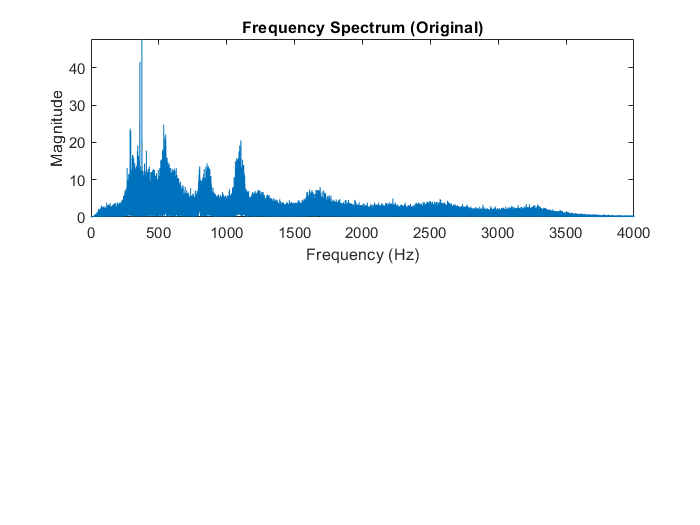

% Full path to the audio file
full_path = 'E:\5th Semester\01-Our notes\EC5011-Digital signal processing\03-Task\02\data_mosquito\non-dengue\train_non_dengue\Voice0038.wav';

% Load audio file
[y, Fs] = audioread(full_path);

% Calculate the time axis
t = (0:length(y)-1) / Fs;

% Frequency spectrum plot of the original filtered signal
N = length(y);
Y = fft(y);
yshift = fftshift(Y);
fshift = (-N/2:N/2-1)*(Fs/N); % Corrected frequency vector
plot(fshift, abs(yshift));
title('Frequency Spectrum (Original)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
xlim([0 Fs/2]);

function [is_dengue] = classify_audio(file_path, num_band1, den_band1, num_band2, den_band2, num_band3, den_band3, L2, threshold)
    targetFs = 8000; % Sampling rate
    % Read the audio file
    [y, Fs] = audioread(file_path);

    % Resample if necessary
    if Fs ~= targetFs
        y = resample(y, targetFs, Fs);
    end
    % Apply noise reduction filter
    %y = wiener2(y, [2 2]);

    % Apply bandpass filters
    y_band1 = filter(num_band1, den_band1, y);
    y_band2 = filter(num_band2, den_band2, y);
    y_band3 = filter(num_band3, den_band3, y);

    % Compute FFT
    Y_band1 = fft(y_band1, L2);
    Y_band2 = fft(y_band2, L2);
    Y_band3 = fft(y_band3, L2);

    % Calculate magnitude spectra
    T_band1 = abs(Y_band1);
    T_band2 = abs(Y_band2);
    T_band3 = abs(Y_band3);

    % Calculate energy ratios
    R_fin = sum(T_band1.^2) + sum(T_band2.^2) + sum(T_band3.^2);

    % Classify based on threshold
    if R_fin > threshold
        disp(['Dengue: ', file_path]);
        is_dengue = true;
    else
        disp(['Non-Dengue: ', file_path]);
        is_dengue = false;
    end
end
function playCallback(~, ~, player)
    play(player);
end

function stopCallback(~, ~, player)
    stop(player);
end